# 11/15

fingerprint skeleton, Filter(ex2.3?), pseudo-inverse(ex2)

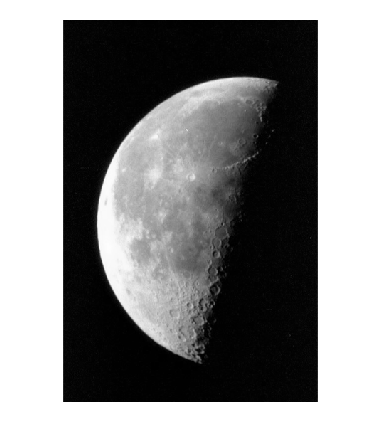

img = im2double(imread("moon.tif"));
figure; imshow(img);

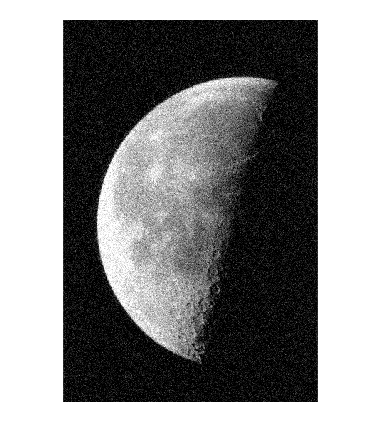

img = imnoise(img, 'gaussian', 0, 0.01);
figure; imshow(img);

h=ones(7,7)/49;
filter_image=imfilter(img,h);
figure; imshow(img);

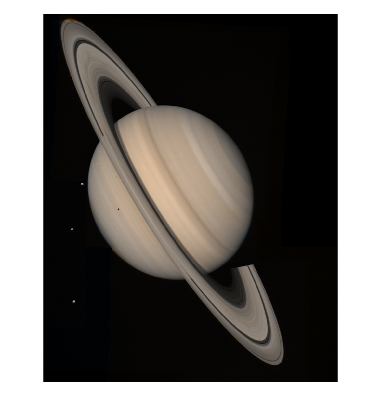

clear all;
RGB = im2double(imread('saturn.png'));
figure; imshow(RGB);

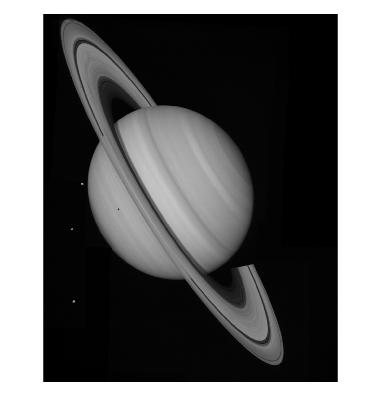

I = rgb2gray(RGB);
figure; imshow(I);

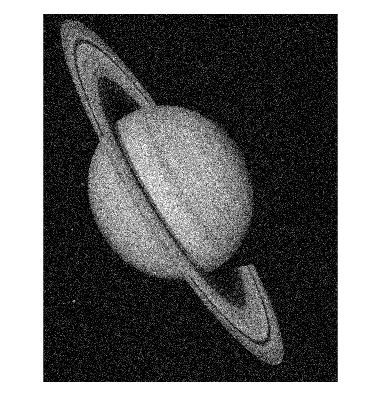

J = imnoise(I, "gaussian", 0, 0.02);
figure; imshow(J);

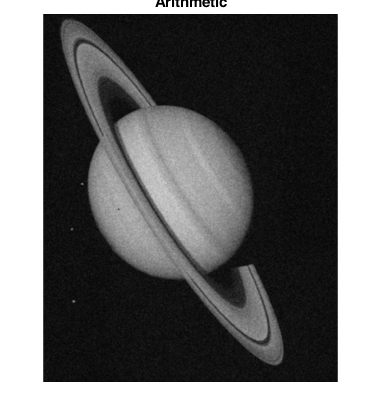

h = ones(7,7)/49;
M = imfilter(J, h);
figure; imshow(M); title("Arithmetic");

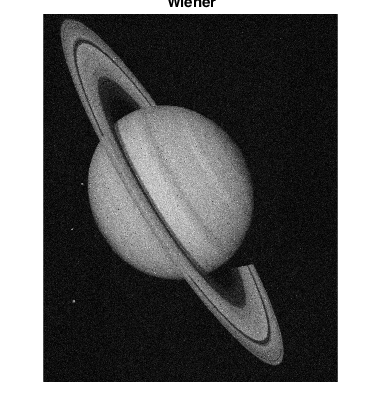

W = wiener2(J, [3 3], 0.02);
figure; imshow(W); title("Wiener");

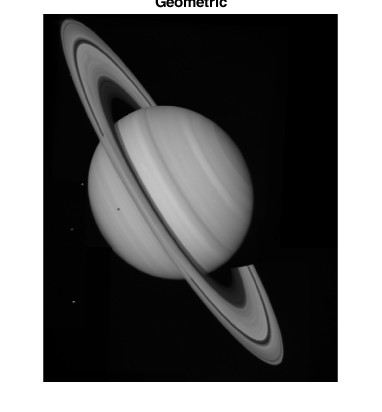

h = ones(7,7);
geo_mean = imfilter(log(I), h, 'replicate');
geo_mean = exp(geo_mean);
geo_mean = geo_mean .^ (1/numel(h));
figure; imshow(geo_mean); title("Geometric");

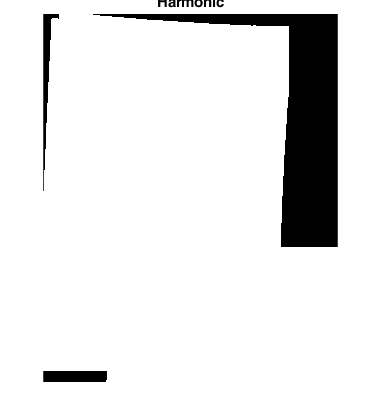

h = ones(3,3);
K = I;
for j = 1:length(I(:))
    if I(j)~=0
        K(j) = 1/I(j);
    end
end
harm_mean = imfilter(K, h);
figure; imshow(harm_mean); title("Harmonic");

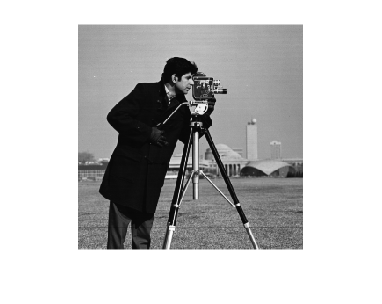

clear all;
img = im2double(imread('cameraman.tif'));
figure; imshow(img);

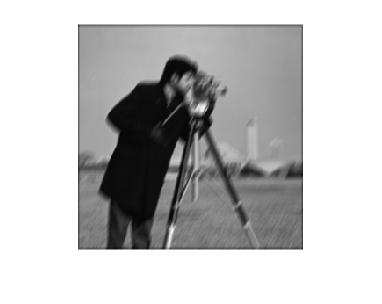

h = fspecial('motion', 9, 60);
blur_img = imfilter(img, h);
figure; imshow(blur_img);

%ex2 hw

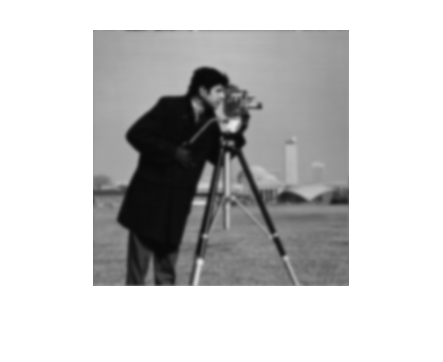

clear all;
cam = im2double(imread('cameraman.tif'));
CAM = fftshift(fft2(cam));
H = fspecial('gaussian', 256, 25); H = mat2gray(H);
BCAM = CAM.*H;
bcam = abs(ifft2(ifftshift(BCAM)));
figure; imshow(bcam);

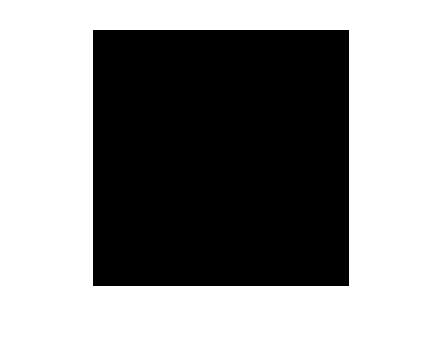

INV_H = 1./H;
inv_cam = abs(ifft2(ifftshift(BCAM.*INV_H)));
figure; imshow(inv_cam);

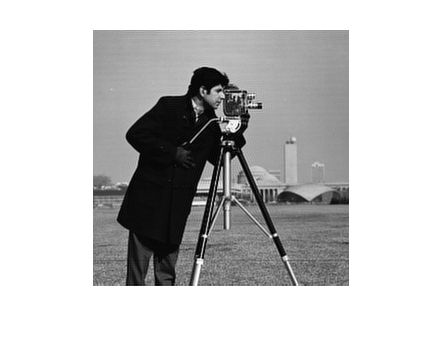


H = fspecial('gaussian', 256, 25); H = mat2gray(H);
P_INV = zeros(size(H));
for j = 1:length(H(:))
    if H(j) > 1e-4
        P_INV(j) = 1/H(j);
    else
        P_INV(j) = 0;
    end
end
P_INV_CAM = BCAM.*P_INV;
p_inv_cam = abs(ifft2(ifftshift(P_INV_CAM)));
figure; imshow(p_inv_cam);

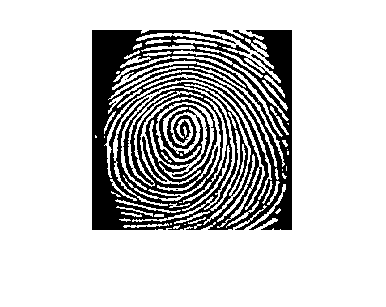

clear all;
I = imread('ori_1.jpg');
J = 1-(I(:,:,1)>150);
figure; imshow(J);

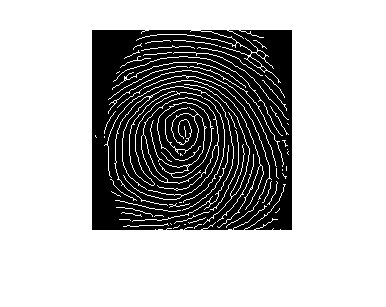

skel = bwmorph(J, 'skel', inf);
figure; imshow(skel);